addpath('Classes')
addpath('Simulink Models')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Dual Sliding Surface Control Research Script

This script aids in the research of a dual sliding surface control scheme utilizing Lyapunov stability arguments for guarantee of trajectory tracking performance under certain conditions. These conditions are partially determined in this script. This methodology will take advantage of the decoupling assumptions and work with the nonlinear, decoupled, EOMs. For each decoupled direction, a sliding surface is defined in terms of error states in the position variable. A second sliding surface involving absolute angular states is defined. The research attempts to provide a stability argument for the tracking error using the first sliding surface while maintaning reasonable constraints on the angles through the second sliding surface. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 


%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;
end

%Define some symbolic variables that will be used in the dual sliding surface control law
syms lambda_x lambda_beta lambda_y lambda_gamma T_tilde_beta T_hat_beta_1 T_hat_beta_2 T_tilde_gamma T_hat_gamma_1 T_hat_gamma_2 K_x K_beta K_y K_gamma S_x S_beta S_dot_x S_dot_beta S_y S_gamma S_dot_y S_dot_gamma


## System 1 - x direction

### Sliding Surface for x 


$$\begin{array}{l}

S_x = e_\dot{x} + \lambda_x \, e_x\\

S_x = \dot{x}_s - \dot{x} + \lambda_x\,  (x_s - x)

\end{array}$$



Sx_eqn = S_x == VDefs.x_dot_s - VDefs.x_dot + lambda_x*(VDefs.x_s - VDefs.x)

$$Sx\_eqn = S_{x}={\dot{x}}_{s}-\dot{x}-\lambda_{x}\,\left(x-x_{s}\right)$$


$$\begin{array}{l}

\dot{S}_x = e_\ddot{x} + \lambda_x e_\dot{x}\\

\dot{S}_x = \ddot{x}_s - \ddot{x} + \lambda_x (\dot{x}_s - \dot{x})\\



\end{array}$$


Sxd_eqn = S_dot_x == VDefs.x_ddot_s - rhs(NL_Dcpld_EOMs.NumDcpldEOMs(2)) + lambda_x*(VDefs.x_dot_s - VDefs.x_dot)

$$Sxd\_eqn = {\dot{S}}_{x}={\ddot{x}}_{s}+\frac{0.3235\,T_{\beta }}{0.2100\,x^{2}+0.0182}-\lambda_{x}\,\left(\dot{x}-{\dot{x}}_{s}\right)-\frac{0.0732\,\sin\left(\beta \right)+1.4715\,x^{2}\,\sin\left(\beta \right)+0.0135\,{\dot{\beta }}^{2}\,x-0.0952\,x\,\cos\left(\beta \right)+0.1500\,{\dot{\beta }}^{2}\,x^{3}+0.0194\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}$$

### Sliding Surface for Beta


$$\begin{array}{l}

S_\beta = \dot{\beta} + \lambda_\beta \, \beta\\


\end{array}$$



Sb_eqn = S_beta == VDefs.beta_dot + lambda_beta*VDefs.beta

$$Sb\_eqn = S_{\beta }=\dot{\beta }+\beta \,\lambda_{\beta }$$


$$\begin{array}{l}


\dot{S}_\beta  =  \ddot{\beta}  + \lambda_\beta  \,  \dot{\beta}\\


\end{array}$$


Sbd_eqn = S_dot_beta ==  rhs(NL_Dcpld_EOMs.NumDcpldEOMs(4)) + lambda_beta*VDefs.beta_dot

$$Sbd\_eqn = {\dot{S}}_{\beta }=\dot{\beta }\,\lambda_{\beta }+\frac{7\,T_{\beta }}{0.2100\,x^{2}+0.0182}+\frac{1.1831\,\sin\left(\beta \right)-0.0097\,{\dot{\beta }}^{2}\,x+2.0601\,x\,\cos\left(\beta \right)-0.4200\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}$$

## System 2 - y direction

### Sliding Surface for y 


$$\begin{array}{l}

S_y = e_\dot{y} + \lambda_y \, e_y\\

S_y = \dot{y}_s - \dot{y} + \lambda_y\,  (y_s - y)

\end{array}$$



Sy_eqn = S_y == VDefs.y_dot_s - VDefs.y_dot + lambda_y*(VDefs.y_s - VDefs.y)

$$Sy\_eqn = S_{y}={\dot{y}}_{s}-\dot{y}-\lambda_{y}\,\left(y-y_{s}\right)$$


$$\begin{array}{l}

\dot{S}_y = e_\ddot{y} + \lambda_y e_\dot{y}\\

\dot{S}_y = \ddot{y}_s - \ddot{y} + \lambda_y (\dot{y}_s - \dot{y})\\



\end{array}$$


Syd_eqn = S_dot_y == VDefs.y_ddot_s - rhs(NL_Dcpld_EOMs.NumDcpldEOMs(6)) + lambda_y*(VDefs.y_dot_s - VDefs.y_dot)

$$Syd\_eqn = {\dot{S}}_{y}={\ddot{y}}_{s}-\frac{0.3235\,T_{\gamma }}{0.2100\,y^{2}+0.0182}-\lambda_{y}\,\left(\dot{y}-{\dot{y}}_{s}\right)+\frac{0.0732\,\sin\left(\gamma \right)+1.4715\,y^{2}\,\sin\left(\gamma \right)-0.0135\,{\dot{\gamma }}^{2}\,y+0.0952\,y\,\cos\left(\gamma \right)-0.1500\,{\dot{\gamma }}^{2}\,y^{3}+0.0194\,\dot{\gamma }\,y\,\dot{y}}{0.2100\,y^{2}+0.0182}$$

### Sliding Surface for Gamma


$$\begin{array}{l}

S_\gamma = \dot{\gamma} + \lambda_\gamma \, \gamma\\


\end{array}$$



Sg_eqn = S_gamma == VDefs.gamma_dot + lambda_gamma*VDefs.gamma

$$Sg\_eqn = S_{\gamma }=\dot{\gamma }+\gamma \,\lambda_{\gamma }$$


$$\begin{array}{l}


\dot{S}_\gamma  =  \ddot{\gamma}  + \lambda_\gamma  \,  \dot{\gamma}\\


\end{array}$$


Sgd_eqn = S_dot_gamma ==  rhs(NL_Dcpld_EOMs.NumDcpldEOMs(8)) + lambda_gamma*VDefs.gamma_dot

$$Sgd\_eqn = {\dot{S}}_{\gamma }=\dot{\gamma }\,\lambda_{\gamma }+\frac{7\,T_{\gamma }}{0.2100\,y^{2}+0.0182}+\frac{1.1831\,\sin\left(\gamma \right)+0.0097\,{\dot{\gamma }}^{2}\,y-2.0601\,y\,\cos\left(\gamma \right)-0.4200\,\dot{\gamma }\,y\,\dot{y}}{0.2100\,y^{2}+0.0182}$$

## Choose lambdas (controller tuning)

lambda_x_num = 1;
lambda_beta_num = lambda_x_num;

%Substitute in the numerical values for the lambndas into the symbolic results


lambda_y_num = 1;
lambda_gamma_num = lambda_y_num;

%Substitute in the numerical values for the lambndas into the symbolic results


## Desired Trajectory in x and y

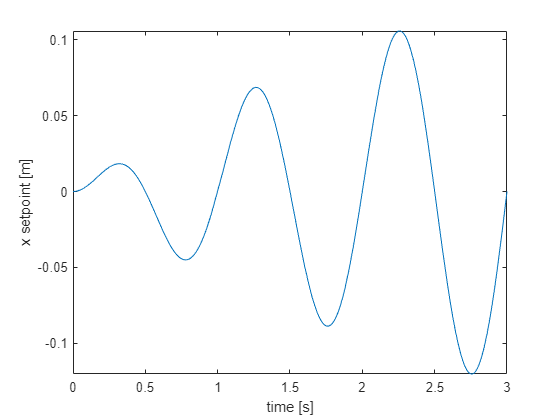


r_sim = .2; % radius of circular trajectory [m]
freq = 1; %rotations per second
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 

%Trajectory symfuns figure 8
des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
% des_traj_sym_x(VDefs.t) = 0;
% des_traj_sym_y(VDefs.t) = 0;

%Overlay first order smoothing function
T = 3; %Time constant for first order response

%Trajectory symfuns with first order smoothing overlayed
des_traj_sym_x(VDefs.t) = des_traj_sym_x(VDefs.t)*(1-exp(-VDefs.t/T));
des_traj_sym_y(VDefs.t) = des_traj_sym_y(VDefs.t)*(1-exp(-VDefs.t/T));

fplot(des_traj_sym_x) 
xlim([0 2*pi/omega_sim*3]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

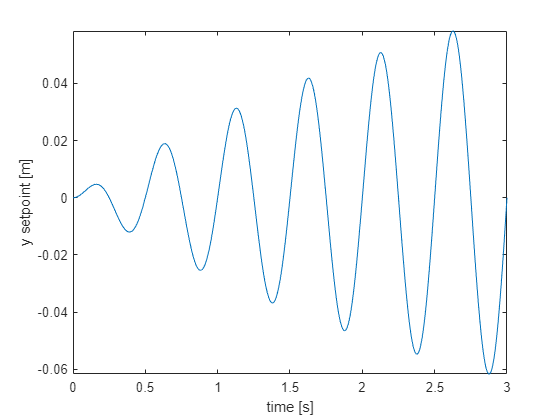


fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim*3]); 
ylabel('y setpoint [m]')
xlabel('time [s]')


%Trajectory's derivatives
des_traj_sym_dot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_x(t) = 0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)-1.2566\,\cos\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$

des_traj_sym_dot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_y(t) = 1.2566\,{\sin\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)-1.2566\,{\cos\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)+0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)$$

des_traj_sym_ddot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t,2)

$$des\_traj\_sym\_ddot\_x(t) = 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)+7.8957\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$

des_traj_sym_ddot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t,2)

$$des\_traj\_sym\_ddot\_y(t) = 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\cos\left(6.2832\,t\right)}^{2}-0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\sin\left(6.2832\,t\right)}^{2}-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)+31.5827\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$


%x_s_vec and x_y_vec
des_traj_sym_x = [des_traj_sym_x;des_traj_sym_dot_x;des_traj_sym_ddot_x]

$$des\_traj\_sym\_x(t) = \left[\begin{array}{c} -0.2000\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)-1.2566\,\cos\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)+7.8957\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right) \end{array}\right]$$

des_traj_sym_y = [des_traj_sym_y;des_traj_sym_dot_y;des_traj_sym_ddot_y]

$$des\_traj\_sym\_y(t) = \left[\begin{array}{c} -0.2000\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 1.2566\,{\sin\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)-1.2566\,{\cos\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)+0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\\ 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\cos\left(6.2832\,t\right)}^{2}-0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\sin\left(6.2832\,t\right)}^{2}-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)+31.5827\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right) \end{array}\right]$$

## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

%% System 1 MATLAB Function Blocks
% Input gain for x
sim_path_string = strcat('Dual_Sliding_Surface_Control_Try2','/Controller x dimension/input gain x');
load_system('Dual_Sliding_Surface_Control_Try2');
input_chars = {'x', 'x_dot', 'beta', 'beta_dot'};
matlabFunctionBlock(sim_path_string, NL_Dcpld_EOMs.Num_g_1(2) , 'FunctionName', 'g_1_2','Vars',input_chars, 'Outputs', {'g_1_2'})

% Input gain for beta
sim_path_string = strcat('Dual_Sliding_Surface_Control_Try2','/Controller x dimension/input gain beta');
load_system('Dual_Sliding_Surface_Control_Try2');
input_chars = {'x', 'x_dot', 'beta', 'beta_dot'};
matlabFunctionBlock(sim_path_string, NL_Dcpld_EOMs.Num_g_1(4) , 'FunctionName', 'g_1_4','Vars',input_chars, 'Outputs', {'g_1_4'})

%% System 2 MATLAB Function Blocks
% Input gain for y
sim_path_string = strcat('Dual_Sliding_Surface_Control_Try2','/Controller y dimension/input gain y');
load_system('Dual_Sliding_Surface_Control_Try2');
input_chars = {'y', 'y_dot', 'gamma', 'gamma_dot'};
matlabFunctionBlock(sim_path_string, NL_Dcpld_EOMs.Num_g_2(2) , 'FunctionName', 'g_2_2','Vars',input_chars, 'Outputs', {'g_2_2'})

% Input gain for gamma
sim_path_string = strcat('Dual_Sliding_Surface_Control_Try2','/Controller y dimension/input gain gamma');
load_system('Dual_Sliding_Surface_Control_Try2');
input_chars = {'y', 'y_dot', 'gamma', 'gamma_dot'};
matlabFunctionBlock(sim_path_string, NL_Dcpld_EOMs.Num_g_2(4) , 'FunctionName', 'g_2_4','Vars',input_chars, 'Outputs', {'g_2_4'})



%%Trajectory Setpoints 
%x direction
sim_path_string = strcat('Dual_Sliding_Surface_Control','/x_Setpoint_Function');
load_system('Dual_Sliding_Surface_Control');
matlabFunctionBlock(sim_path_string, des_traj_sym_x,'FunctionName', 'x_setpoint')

%y direction
sim_path_string = strcat('Dual_Sliding_Surface_Control','/y_Setpoint_Function');
load_system('Dual_Sliding_Surface_Control');
matlabFunctionBlock(sim_path_string, des_traj_sym_y,'FunctionName', 'y_setpoint')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat('Dual_Sliding_Surface_Control','/Plant/Plant_Function');
load_system('Dual_Sliding_Surface_Control');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
%                 output_chars = {'x_dot', 'x_ddot', 'beta_dot', 'beta_ddot','y_dot', 'y_ddot', 'gamma_dot', 'gamma_ddot' };
matlabFunctionBlock(sim_path_string, rhs(NL_Dcpld_EOMs.NumDcpldEOMs), 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Dual Sliding Surface Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*3;
% tspan = [0 2] %For checking Zach's regulator gains
%Specify initial conditions

x_0 = rand(8,1); %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

Tmax = 75/1000 %75mNm

Tmax = 0.0750



simout_PID = sim('Dual_Sliding_Surface_Control_Try2')

simout_PID =   Simulink.SimulationOutput:

                   tout: [4173x1 double] 
                      u: [4173x2 double] 
                      x: [4173x8 double] 
                x_s_vec: [4173x3 double] 
                y_s_vec: [4173x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
